X=-150%[-150:0.1:150];

X = -150

Y=5,Z=107.660;

Y = 5

%---------------------INVERSE KINEMATICS---------------------%
L_4=66,L_5=12,L_6=107;

L_4 = 66

L_5 = 12

theta_2=real(acosd((-2*L_4*L_6+(4*L_4^2*L_6^2-4*L_6^2*(-X.^2-Y^2+L_5^2+L_4^2)).^0.5)/(2*L_6^2)))

theta_2 = 38.6171

theta_1=atan2d(Y,X)-atan2d(L_5,L_4+L_6*cosd(theta_2))

theta_1 = 173.5048

L_3=Z-L_6*sind(theta_2)-22

L_3 = 18.8800

L_4=66,L_5=12,L_6=107;

L_4 = 66

L_5 = 12

l(1)=Link([0,17+5,0,0,0])

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=1.571      
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


%l(1).qlim=[-pi pi]
l(2)=Link([0,0,L_4,pi/2,1])

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=1.571      
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


l(2).qlim=[0 50]

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=1.571      
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


l(3)=Link([0,-L_5,0,pi/2,0])

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


l(3).offset=pi/2

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=1.571      
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


%l(3).qlim=[-pi/2 pi/2]
l(4)=Link([0,L_6,0,0,0])

 
l = 
Revolute(std):  theta=q1   d=22          a=0           alpha=0           offset=0          
Prismatic(std): theta=0             d=q2 a=66          alpha=1.571       offset=0          
Revolute(std):  theta=q3   d=-12         a=0           alpha=1.571       offset=1.571      
Revolute(std):  theta=q4   d=107         a=0           alpha=0           offset=0          


%l(4).qlim=[-pi/2 pi/2]

Rob=SerialLink(l,'name','Robot')

 
Rob = 
 
Robot:: 4 axis, RPRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         22|          0|          0|          0|
|  2|          0|         q2|         66|     1.5708|          0|
|  3|         q3|        -12|          0|     1.5708|     1.5708|
|  4|         q4|        107|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


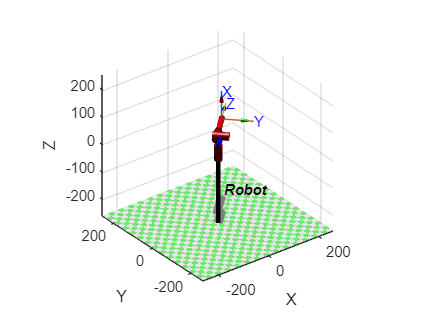

%Rob.teach();
Rob.plot([pi/4,0,0,0]);